# Creating a Fitness Tracker App

Prepared by: Group 1 (Thalia Karentsopoulou, Pantelis Naoum)

MATLAB with AI Hackathon, Athens 2023

In order to create the fitness tracker we will collect sensor Data and save it to the MATLAB Drive. The data we will be importing for starters in this software will be the Latitude, the Longitude and the Timestamp (time interval) at which the data are taken. We are able to also import data from the Accelerometer as well as the time interval of the accelerometer data collection.

## Preparing Data

To work with the data, we must first load it into the workspace and store the variables that are going to be used in this example. While we can double click on the data to load it, we will use the [`load`](https://www.mathworks.com/help/matlab/ref/load.html) command to make this process easier to replicate.

%Load the data file and extract the data required

load('Group1_measurments.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

We have now imported succesfully the necessary data of lattitude, longitude and their timestamp. We will proceed with the data manipulation in order to export the necessary values needed in the fitness tracker

## Visualizing the Distance Covered

Given the Latitude and Longitude as 'long' and 'lat' we will visualise for the user the distance which he has covered in the given excersise (data file) using the geoplot. The `geoplot` function in MATLAB is part of the Mapping Toolbox and is used to create 2D geographic plots on map axes. It allows you to visualize geospatial data, such as points, lines, polygons, and grids, on maps. It can be used as follows:

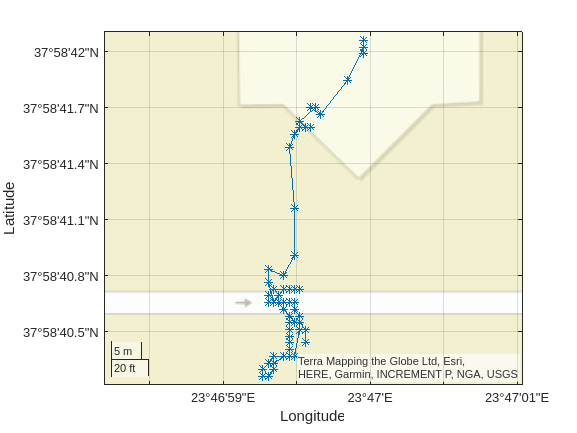

geoplot(lat,lon,'-*')
geobasemap streets

## Calculate the Covered Distance

In order to calculate the covered distance from the latitude and longitude intervals, we may use what is known as the "Harvesine Formula". The Haversine formula is a mathematical formula used to calculate the distance between two points on the surface of a sphere, such as the Earth, given their latitude and longitude coordinates. It is commonly used in geospatial calculations.

Given 2 points if $\varphi_{1\;} ,\varphi_{2\;}$- are the latitude of point 1 and latitude of point 2 and $\lambda_{1\;} ,\lambda_{2\;}$are the longitude of point 1 and longitude of point 2, then the distance between them (in meters) is:

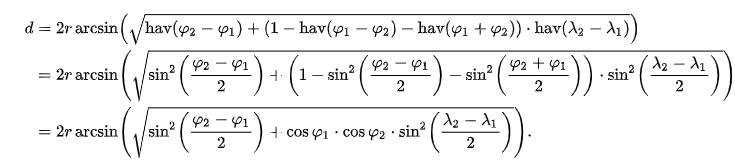

For this reason we create an .m function file to provide us the distance between 2 points given their spatial coordinates.It accepts as input the lat and lon arrays and outputs the array of their distance:

Therefore:

%Calculate the distance between each position of (lat,lon) using Harvesine
displacement = HaversineDistance(lat, lon);

We may also calculate for every time interval the 'Distance Elapsed' since the begining of the activity as the array which is the sum of the displacements of all the previous elements of the array 'displacement' - All done in a for loop:

for i = 2:length(displacement)
    distElapsed(i) = sum(displacement(1:i));
end

Finally we may simply calculate the total distance we ran by summing up all the elements of the array 'displacement':

%Calculate the total distance travelled
total_distance = sum(displacement);
disp(['Distance ran     : ', num2str(total_distance),'m']);

Distance ran     : 117.2985m


## Visualizing the Distance and the Velocity of the runner

We have the array of the distance elapsed, but we need to also visualize it in terms of time. It is necessary to correlate the time intervals with the distance correctly as we may also find the velocity using the velocity formula.

Time Stamp: Is the array from the timeElapsed function in order to find the time elapsed (in seconds) from the begining of the running excersise. 

Max Time: is the total amount of time the runner ran found as the max() of the timestamp 

Time duration: is the Δt time interval between the covered distances.

%Calculate the time duration using timeElapsed
timestamp = timeElapsed(positionDatetime);

maxtime = max(timestamp);
disp(['Total Time       : ', num2str(round(maxtime/60,2)),'mins']);

Total Time       : 1.27mins


for ii=1:length(timestamp)-1
    timeduration(ii)=timestamp(ii+1)-timestamp(ii);
end

Therefore since we have the timestamp and the time duration between the position data intervals, we may be able to plot and visualize to our users their excersise:

**Distance Elapsed Graph**:

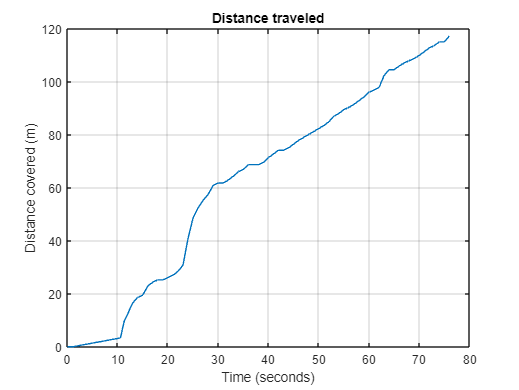

figure
plot(timestamp,[0,distElapsed])
title('Distance traveled');
xlabel('Time (seconds)');
ylabel('Distance covered (m)');
grid on

Velocity Graph

The velocity is the first derivative of the position (displacement) as we have already calculated:


$$v=\frac{\textrm{dx}}{\textrm{dt}}$$


Therefore we are simply calculating it as the fraction (instant velocity):

%Calculate the instant velocity at each time interval
velocity = displacement./timeduration';

And we may plot it below:

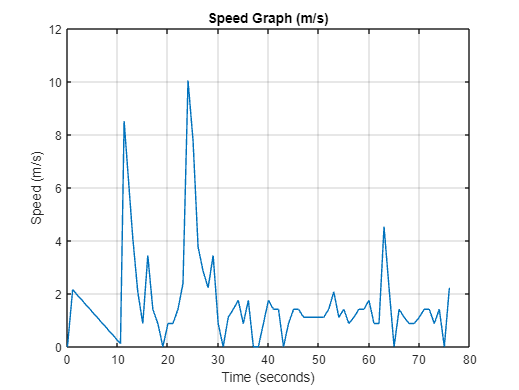

figure
plot(timestamp,[0,velocity'])
title('Speed Graph (m/s)');
xlabel('Time (seconds)');
ylabel('Speed (m/s)');
grid on

The average speed can be simply calculated as the total distance divided by the total time travelled:


$$v_{\textrm{average}} =\frac{S_{\textrm{total}} }{T_{\textrm{total}} }$$


%Average speed in (m/s) with distance (m) and time in (s)
average_speed = round(total_distance/maxtime,2);
disp(['Average speed    : ', num2str(total_distance/maxtime,2),'m/s']);

Average speed    : 1.5m/s


## Calculating the total Steps made

Let’s say that you wanted to track the number of steps taken. One way that this can be done is by calculating the total distance traveled and then dividing it by your stride length. This works because stride is the distance taken for one step so if we look at the units they cancel out as seen below.

     
$$\frac{\textrm{totalDistance}\left(m\right)}{\textrm{stride}\left(\frac{m}{\textrm{step}}\right)}=\frac{m}{\frac{m}{\textrm{step}}}=m*\frac{\textrm{step}}{m}=\textrm{steps}$$


We could assume an average stride of 0.8m, or we can perceive one based on the intensity of the workout. From research we are able to find that depending the velocity of the runner the stride increases:

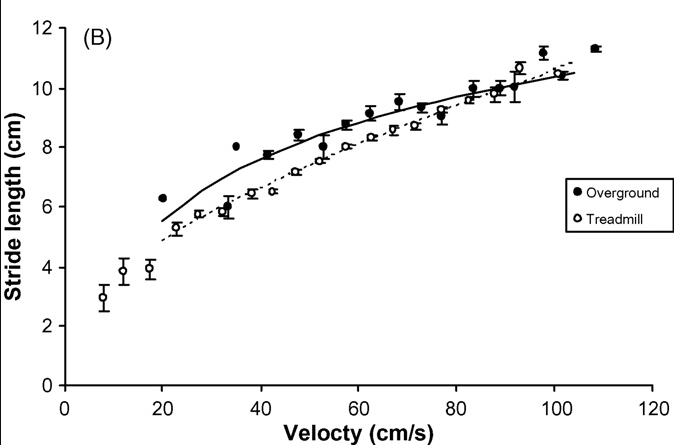

Based on the reasarch of Morio, Yuji & Izawa, Kazuhiro & Omori, Yoshitsugu & Katata, Hironobu & Ishiyama, Daisuke & Koyama, Shingo & Yamano, Yoshihisa. (2019). The Relationship between Walking Speed and Step Length, they extraploate simple correlative relationship between the stride and the speed of an average human:


$$\textrm{stride}\left(\frac{m}{\textrm{step}}\right)=\textrm{average}\;\textrm{speed}\left(\frac{m}{s}\right)*0\ldotp 5981$$


factor which is based on the human characteristics (height,weight, gender) but it will be complicated to calculate for this particular project indivudually. Therefore we may calculate the stride as. 

stride_length = average_speed*0.5981;
disp(['Stride: ', num2str(stride_length),' m/step']);

Stride: 0.92107 m/step


Therfore the total steps taken are calculated from the distance divided by the stride:

% Calculate the steps taken
steps_taken = round(total_distance / stride_length,0);
disp(['Steps Taken      : ', num2str(steps_taken),'steps']);

Steps Taken      : 127steps


## Calculating the Calories Burned

We now calculate the calories burned using the MET. MET stands for Metabolic Equivalent of Task. It is a unit used to estimate the energy expenditure or calorie burning rate of various physical activities. MET represents the ratio of the rate of energy expended during a specific activity to the rate of energy expended at rest. 

In order to calculate the calroies burned, the formula to use is: METs x 3.5 x (your body weight in [kilograms](https://www.metric-conversions.org/weight/pounds-to-kilograms.htm)) / 200 = calories burned per minute.


$$Q\left(\frac{\textrm{kcal}}{\min }\right)=\textrm{MET}*3\ldotp 5*\frac{W\left(\textrm{kg}\right)}{200}$$


Therefore it is necessary to ask the user for his weight data:

weight = 80;

Then the next step is to evaluate the MET depending the excersise as per reseachers have calculated: We may evaluate a relationship between speed and MET:

MET_speed = [0.88889, 1.11111, 1.333333, 1.55556, 1.7778, 2.0000, 2.22222];
MET       = [2.8      3.0      3.5       4.3      5.0     7.0     8.3    ];

By interpolating the above we may get a polynomial interpolation with the following equation:


$$y=3,0857x^2 -5,4214x+5,2$$


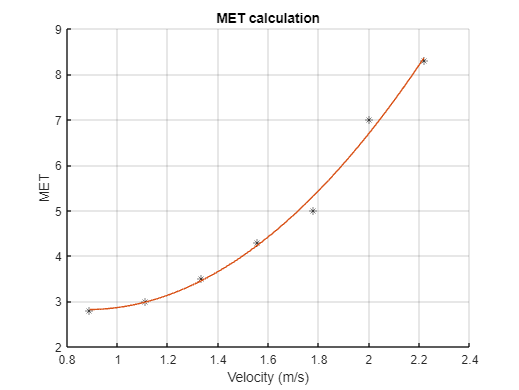

MET_sp_vr = 0.88889:0.01:2.22222;
MET_calc  = 3.0857.*(MET_sp_vr.^2)-5.4214.*(MET_sp_vr)+5.2;

figure
hold on
plot(MET_speed, MET, 'k*')
plot(MET_sp_vr, MET_calc)
title('MET calculation');
xlabel('Velocity (m/s)');
ylabel('MET');
grid on

Therefore, given the average speed of our workout we calculate the METs and using the MET we calculate the calories burned from the given excersise:

%Find total time in seconds
total_time = (maxtime/60)

total_time = 1.2664

%Use met to find the calories per minute
met  = 3.0857.*(average_speed.^2)-5.4214.*(average_speed)+5.2;
calories_burned_per_minute = (met * 3.5 * weight)/200;
%Therefore the total calories are:
total_calories = calories_burned_per_minute * total_time;
disp(['Calories burned      : ', num2str(total_calories),'kcal']);

Calories burned      : 7.3919kcal


## Prototype App Deployment

In order for our application to output the data to the user correctly there is a certain process it must follow:

- Ask details about the user (Input Gender, Age, Weight, Height)

- Ask the user to allow tracking (GDPR)

- Choose a goal (Step goal)

- Begin workout and End workout (Generate data file)

- Import file and perform calculations using MATLAB 

- Show workout results (Total distance, Total time ran, Steps taken, Calories burned, Distance, Velocity and Geoplot graph)


disp('Welcome to Fitness Tracking App')

Welcome to Fitness Tracking App




%Ask user to prompt info
age = input('Please enter your age (years): ');
while (age>100 ||age <1 )
    age = input('Please enter a valid age: ');
end
gender = input('Please enter your gender.Type "1" for male and "2" for female ');
height = input('Please enter your height (cm): ');
weight = input('Please enter your weight (kg): ');
goal   = input('Set your step goal (steps): ')

%Begin excersise - thus data are generated and are manipulated as above.
%We extract the necessary data to our UI

disp('-------------------------------------------------------------')
disp('Results from excersise:')
disp('-------------------------------------------------------------')
disp(' Well done! You managed to run!')
disp(['Goal Achieved    : ', num2str(round(steps_taken/goal*100),2),'%']);
disp(['Distance ran     : ', num2str(total_distance),'m']);
disp(['Total Time       : ', num2str(round(maxtime/60,2)),'mins']);
disp(['Steps Taken      : ', num2str(steps_taken),'steps']);
disp(['Average speed    : ', num2str(total_distance/maxtime,2),'m/s']);
disp(['Calories burned      : ', num2str(total_calories),'kcal']);

figure
plot(timestamp,[0,distElapsed])
title('Distance traveled');
xlabel('Time (seconds)');
ylabel('Distance covered (m)');
grid on

figure
plot(timestamp,[0,velocity'])
title('Speed Graph (m/s)');
xlabel('Time (seconds)');
ylabel('Speed (m/s)');
grid on

figure
geoplot(lat,lon,'-*')
geobasemap streets